# META 3

16. Carregue a estrutura de dados guardada no último ponto da meta anterior

dados = load("dados.mat").dados;

17. Considerando as melhores características extraídas dos sinais no tempo e frequência nos pontos 8 e 14, respetivamente, aplique um classificador para a identificação automatizada dos dígitos através das características extraídas. Para o efeito deverá usar um modelo à sua escolha (por exemplo Minimum Distance ou um sistema de regras if/else) utilizando como features as características extraídas dos sinais no tempo e frequência nos pontos 8 e 14. Guarde na sua estrutura de dados o resultado da classificação.

% Combinar as melhores features
for i = 1:length(dados)
    dados(i).features = [...
        dados(i).energiaTotal,...
        dados(i).taxaCruzamentoZeros,...
        dados(i).tAmplitudeMaxima,...
        dados(i).par,...
        dados(i).entropia,...
        dados(i).spectralSlope];
end

% Criar matriz de features e vetor de rótulos
X = reshape([dados.features], 6, [])';
y_true = [dados.digito]';

% Calcular centroides (médias) das features por dígito
centroides = zeros(10, 6);
for digito = 0:9
    idx = y_true == digito;
    centroides(digito + 1, :) = mean(X(idx, :), 1);
end

% Classificação: mínimo da distância euclidiana
y_pred = zeros(size(y_true));
for i = 1:size(X, 1)
    distancias = vecnorm(centroides - X(i, :), 2, 2);
    [~, classe] = min(distancias);
    y_pred(i) = classe - 1;
end

% Guardar resultados
for i = 1:length(dados)
    dados(i).classificacao = y_pred(i);
end


18. Compare os dígitos atribuídos a cada áudio a partir do classificador usado no ponto anterior com os dígitos reais e defina a percentagem de acertos como: Acertos = Dígitos identificados corretamente Total de dígitos  100 Comente os resultados.

acertos = sum(y_pred == y_true);
total = length(y_true);
percentagemAcertos = acertos / total * 100;

fprintf('Percentagem de acertos: %.2f%%\n', percentagemAcertos);

Percentagem de acertos: 27.00%


19. Compare três tipos de janela diferentes, aplicando-as em intervalos de tempo. Qual é o efeito das diferentes janelas? Comente os resultados. 

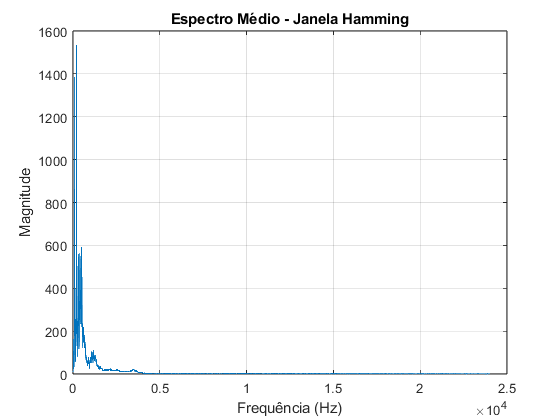

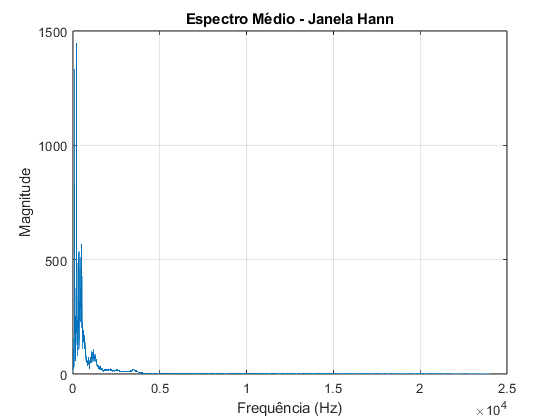

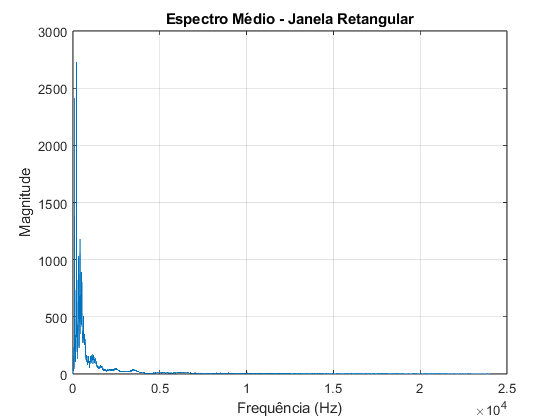


janelas = {@hamming, @hann, @(N) ones(N, 1)};
nomes = {'Hamming', 'Hann', 'Retangular'};

for j = 1:length(janelas)
    janelaFunc = janelas{j};

    espectros = [];

    for i = 1:100  % Usar uma amostra dos dados
        sinal = dados(i).sinal;
        N = length(sinal);
        janela = janelaFunc(N);
        sinalJanela = sinal .* janela;

        Y = abs(fft(sinalJanela));
        Y = Y(1:N/2);  % Frequências positivas
        espectros = [espectros; Y'];
    end

    mediaEspectro = mean(espectros, 1);
    freq = linspace(0, dados(1).taxaAmostragem / 2, length(mediaEspectro));

    figure;
    plot(freq, mediaEspectro);
    title(['Espectro Médio - Janela ', nomes{j}]);
    xlabel('Frequência (Hz)');
    ylabel('Magnitude');
    grid on;
end

20. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

save('dados.mat', 'dados');